Analysis of a 1x1 homogenous layout which contains two identical copies of a model. This is intended to show if there is an instability in the biomass ratios at various timestep lengths

It uses the data file **twindat.m**

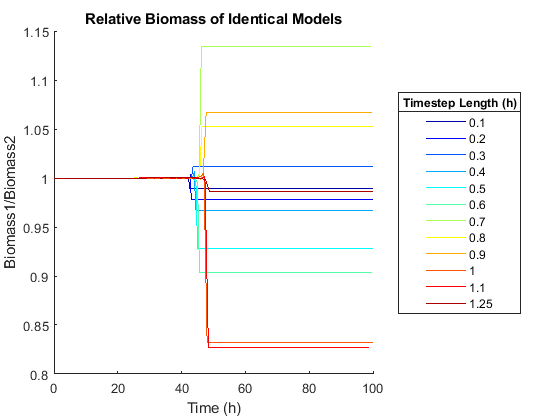

%plot just the data that uses the original maintenance reaction method ("all or nothing")
ot = twindat(~twindat.maint_replaced,:); %'original twin'

[nrows,ncols] = size(ot);
colors = jet(nrows);
legendstr = arrayfun(@(x) num2str(x),ot.ts,'uniformoutput',false);
figure();
hold on;
for i = 1:nrows
    plot(ot.t{i},ot.biomass1{i} ./ ot.biomass2{i},'Color',colors(i,:));
end
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep Length (h)');
xlabel('Time (h)');
ylabel('Biomass1/Biomass2');
title('Relative Biomass of Identical Models');
hold off;

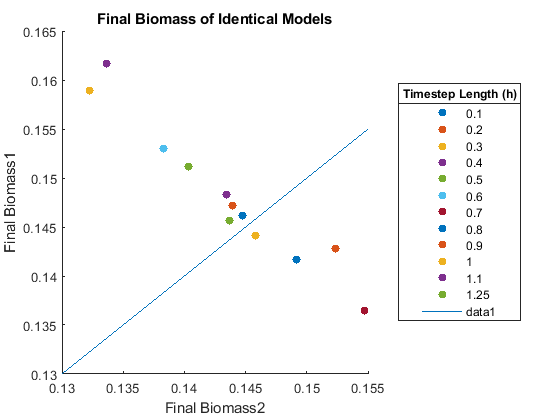


figure();
hold on;
for i = 1:nrows
    scatter(ot.biomass1{i}(end),ot.biomass2{i}(end),'filled');
end
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep Length (h)');
xlabel('Final Biomass2');
ylabel('Final Biomass1');
title('Final Biomass of Identical Models');
refline(1,0);
hold off;

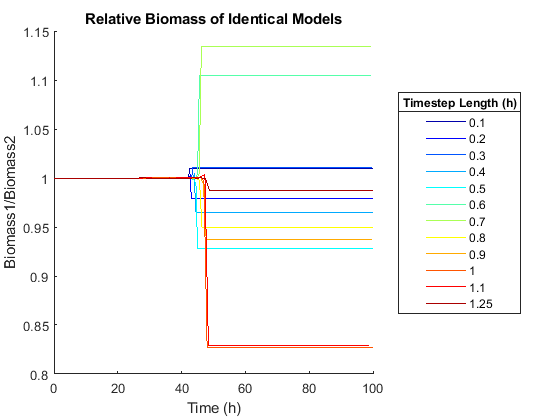


%plot just the data that uses the modified maintenance reaction method ("partial maintenance")
mt = twindat(twindat.maint_replaced,:); %'modified twin'

[nrows,ncols] = size(mt);
colors = jet(nrows);
legendstr = arrayfun(@(x) num2str(x),mt.ts,'uniformoutput',false);
figure();
hold on;
for i = 1:nrows
    plot(mt.t{i},mt.biomass1{i} ./ mt.biomass2{i},'Color',colors(i,:));
end
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep Length (h)');
xlabel('Time (h)');
ylabel('Biomass1/Biomass2');
title('Relative Biomass of Identical Models');
hold off;

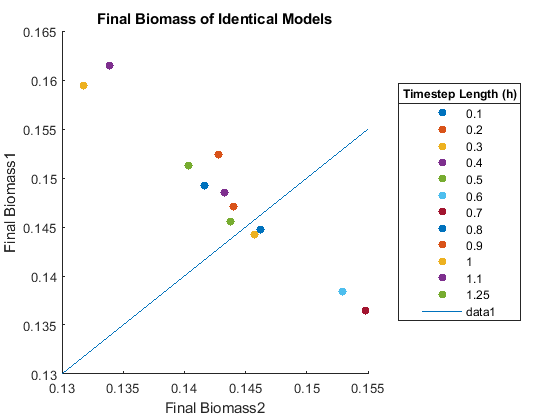


figure();
hold on;
for i = 1:nrows
    scatter(mt.biomass1{i}(end),mt.biomass2{i}(end),'filled');
end
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep Length (h)');
xlabel('Final Biomass2');
ylabel('Final Biomass1');
title('Final Biomass of Identical Models');
refline(1,0);
hold off;

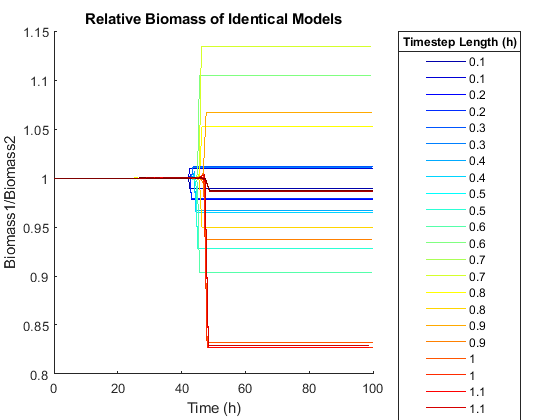

%plot all
twindat = sortrows(twindat,{'ts','maint_replaced'});
[nrows,ncols] = size(twindat);
colors = jet(nrows);
legendstr = arrayfun(@(x) num2str(x),twindat.ts,'uniformoutput',false);
figure();
hold on;
for i = 1:nrows
    plot(twindat.t{i},twindat.biomass1{i} ./ twindat.biomass2{i},'Color',colors(i,:));
end
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep Length (h)');
xlabel('Time (h)');
ylabel('Biomass1/Biomass2');
title('Relative Biomass of Identical Models');
hold off;

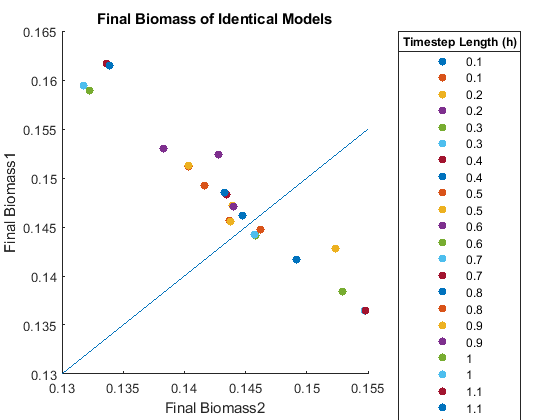


figure();
hold on;
for i = 1:nrows
    scatter(twindat.biomass1{i}(end),twindat.biomass2{i}(end),'filled');
end
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep Length (h)');
xlabel('Final Biomass2');
ylabel('Final Biomass1');
title('Final Biomass of Identical Models');
refline(1,0);
hold off;